# ADML

clear all; clc; close all;

## Load data for all turbines

WT2 = readtable('data.xlsx', 'Sheet', 'No.2WT', 'ReadVariableNames', true);

WT39 = readtable('data.xlsx', 'Sheet', 'No.39WT', 'ReadVariableNames', true);

WT14 = readtable('data.xlsx', 'Sheet', 'No.14WT', 'ReadVariableNames', true);

WT3 = readtable('data.xlsx', 'Sheet', 'No.3', 'ReadVariableNames', true);

numColumns = 27;

% Ensure all datasets have at least `numColumns` columns
WT2 = WT2(:, 1:numColumns);
WT39 = WT39(:, 1:numColumns);
WT14 = WT14(:, 1:numColumns);
WT3 = WT3(:, 1:numColumns);

% Combine data from all turbines
allData = [WT2; WT39; WT14; WT3];

% Number of attributes (columns) and records (rows)
[numRecords, numAttributes] = size(allData);

% Display basic information about the data
fprintf('Number of records (rows): %d\n', numRecords);

Number of records (rows): 4359


fprintf('Number of attributes (columns): %d\n', numAttributes);

Number of attributes (columns): 27



% Display the first few rows of the data
disp('First few rows of the data:');

First few rows of the data:


disp(allData(1:5, :));

       x1           x2          x3        x4        x5        x6        x7        x8          x9         x10       x11      x12       x13       x14    x15     x16       x17       x18       x19      x20       x21      x22       x23       x24       x25       x26       x27  
    _________    _________    ______    ______    ______    ______    ______    ______    __________    ___


% Calculate and display basic statistics for each attribute
min_vals = min(allData);
max_vals = max(allData);
means = mean(allData);
medians = median(allData);
std_devs = std(allData);

% Display the statistics
disp('Minimum values:');

Minimum values:


disp(min_vals);

       x1          x2          x3         x4          x5          x6         x7      x8    x9    x10      x11         x12       x13    x14      x15        x16        x17       x18         x19          x20        x21        x22       x23        x24        x25         x26        x27  
    ________    ________    ________    _______    _________    _______    ______    __    __    


disp('Maximum values:');

Maximum values:


disp(max_vals);

      x1        x2        x3        x4        x5        x6        x7        x8         x9        x10      x11     x12      x13      x14    x15     x16       x17       x18      x19     x20      x21      x22       x23       x24       x25       x26       x27  
    _______    _____    ______    ______    ______    ______    ______    ______    _________    ____    


disp('Means:');

Means:


disp(means);

        x1          x2        x3        x4        x5        x6        x7        x8      x9      x10       x11       x12       x13       x14        x15       x16       x17       x18       x19       x20      x21       x22       x23       x24      x25       x26      x27 
    __________    ______    ______    ______    ______    ______    ______    ______    ___    ______ 


disp('Medians:');

Medians:


disp(medians);

    x1    x2     x3      x4      x5        x6        x7        x8      x9      x10       x11      x12       x13       x14    x15     x16      x17       x18       x19      x20      x21     x22      x23       x24      x25       x26      x27 
    __    __    ____    ____    _____    ______    ______    ______    ___    ______    ______    ____


disp('Standard Deviations:');

Standard Deviations:


disp(std_devs);

       x1         x2        x3        x4        x5        x6        x7        x8      x9      x10       x11       x12       x13       x14       x15       x16       x17       x18      x19       x20       x21       x22       x23       x24       x25       x26       x27  
    ________    ______    ______    ______    ______    ______    ______    ______    ___    ______   

## choosing some of the random attributes

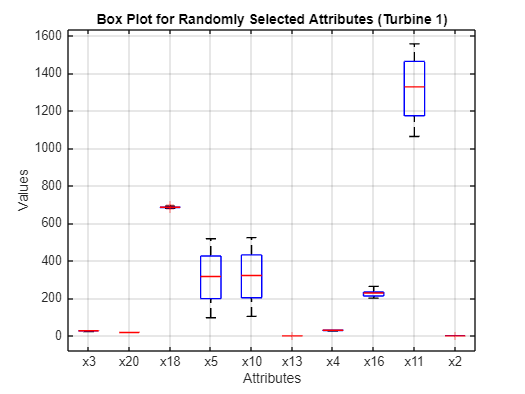

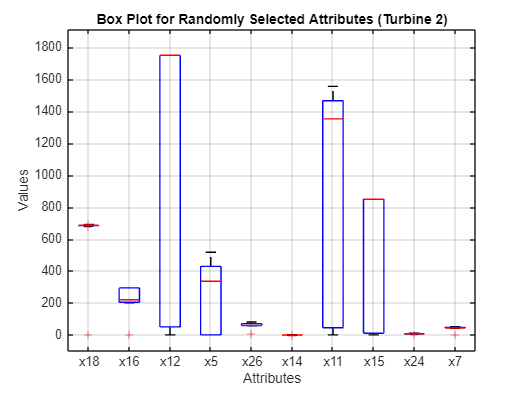

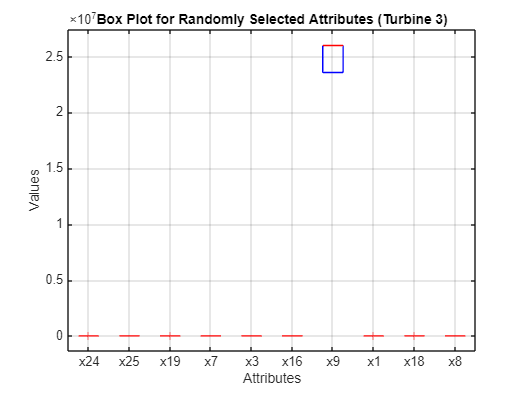

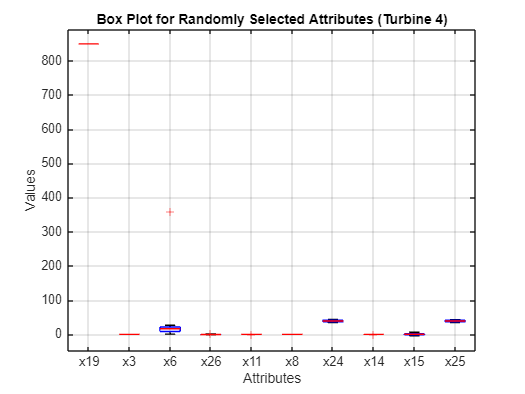

% Get the variable names (attributes) from WT39
attributes = WT39.Properties.VariableNames;

% Loop through each turbine dataset
turbines = {WT2, WT39, WT14, WT3};
for i = 1:length(turbines)
    turbine = turbines{i};
    data = table2array(turbine);  % Convert the table to an array
    
    % Create a figure for box plots
    figure;
    
    % Prepare data for boxplot
    boxData = [];
    labels = {};
    
    % Randomly select 10 attributes (ensure there are enough attributes)
    numAttributes = min(10, length(attributes));  % Handle cases with fewer than 10 attributes
    selectedIndices = randperm(length(attributes), numAttributes);  % Randomly select indices
    selectedAttributes = attributes(selectedIndices);  % Get selected attribute names
    
    for j = 1:length(selectedAttributes)
        attrName = selectedAttributes{j};  % Extract the selected attribute name
        
        % Check if the attribute exists in the current turbine table
        if any(strcmp(turbine.Properties.VariableNames, attrName))
            % Collect the data for the box plot from the corresponding column
            boxData = [boxData; turbine.(attrName)'];  
            labels{end+1} = [attrName];
        else
            disp(['Attribute ', attrName, ' is not present in turbine ', num2str(i)]);
        end
    end

    % Create the box plot
    boxplot(boxData', 'Labels', labels);
    title(['Box Plot for Randomly Selected Attributes (Turbine ', num2str(i), ')']);
    xlabel('Attributes');
    ylabel('Values');
    grid on;
end

## Check for the missing values

% Check for missing values in each table
missingWT2 = sum(ismissing(WT2));
missingWT39 = sum(ismissing(WT39));
missingWT14 = sum(ismissing(WT14));
missingWT3 = sum(ismissing(WT3));

% Display the results
disp('Missing values in WT2:');

Missing values in WT2:


disp(missingWT2);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0




disp('Missing values in WT39:');

Missing values in WT39:


disp(missingWT39);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0




disp('Missing values in WT14:');

Missing values in WT14:


disp(missingWT14);

     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0




disp('Missing values in WT3:');

Missing values in WT3:


disp(missingWT3);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



sum(missingWT3), sum(missingWT14), sum(missingWT39), sum(missingWT2)

ans = 0

ans = 1

ans = 0

ans = 0

% remove observation with missing value
WT14 = rmmissing(WT14);
disp('Size of WT14 after removing missing values:');

Size of WT14 after removing missing values:


disp(size(WT14));

   685    27



## DATA PRETREATMENT

## Check if all tables have equal number of columns

size(WT3), size(WT39), size(WT2), size(WT14)

ans =    698    27


ans =         1405          27


ans =         1570          27


ans =    685    27


% The number of the variables are not the same so we have to correct this

## Which variables should we remove and which turbines should we choose for our model?

% Get the number of columns for each dataset
numColsWT2 = width(WT2);
numColsWT3 = width(WT3);
numColsWT14 = width(WT14);
numColsWT39 = width(WT39);

% Get the variable names of each dataset
varNamesWT2 = WT2.Properties.VariableNames;
varNamesWT3 = WT3.Properties.VariableNames;
varNamesWT14 = WT14.Properties.VariableNames;
varNamesWT39 = WT39.Properties.VariableNames;

% Find common variable names across all datasets
commonVars = intersect(intersect(varNamesWT2, varNamesWT3), ...
                       intersect(varNamesWT14, varNamesWT39));

% Display common variable names
disp('Common Variable Names:');

Common Variable Names:


disp(commonVars);

    {'x1'}    {'x10'}    {'x11'}    {'x12'}    {'x13'}    {'x14'}    {'x15'}    {'x16'}    {'x17'}    {'x18'}    {'x19'}    {'x2'}    {'x20'}    {'x21'}    {'x22'}    {'x23'}    {'x24'}    {'x25'}    {'x26'}    {'x27'}    {'x3'}    {'x4'}    {'x5'}    {'x6'}    {'x7'}    {'x8'}    {'x9'}




% Remove non-common columns from each dataset
WT2_filtered = WT2(:, ismember(varNamesWT2, commonVars));
WT3_filtered = WT3(:, ismember(varNamesWT3, commonVars));
WT14_filtered = WT14(:, ismember(varNamesWT14, commonVars));
WT39_filtered = WT39(:, ismember(varNamesWT39, commonVars));

% Now all filtered datasets should have the same columns
disp('Filtered Datasets:');

Filtered Datasets:


disp(size(WT2_filtered));

        1570          27



disp(size(WT3_filtered));

   698    27



disp(size(WT14_filtered));

   686    27



disp(size(WT39_filtered));

        1405          27



% Assuming WT2_filtered, WT3_filtered, WT14_filtered, WT39_filtered are available

% Calculate the means for each filtered dataset
meanWT2 = mean(table2array(WT2_filtered), 1);    
meanWT3 = mean(table2array(WT3_filtered), 1);    
meanWT14 = mean(table2array(WT14_filtered), 1);  
meanWT39 = mean(table2array(WT39_filtered), 1);  

% Combine means into a single table
meansTable = table(meanWT2', meanWT3', meanWT14', meanWT39', ...
                   'VariableNames', {'WT2_Mean', 'WT3_Mean', 'WT14_Mean', 'WT39_Mean'});

% Get the variable names for the filtered datasets
commonVarNames = WT2_filtered.Properties.VariableNames;

% Set the row names to the variable names
meansTable.Properties.RowNames = commonVarNames;

% Display the combined means table
disp(meansTable);

            WT2_Mean      WT3_Mean     WT14_Mean     WT39_Mean 
           __________    __________    __________    __________

    x1     -0.0074363             0    -0.0093516    -0.0087091
    x2      -0.011617        49.986    -0.0082109     -0.010234
    x3         26.312      0.044193        50.848        28.644
    x4          29.28        13.457        51.691        31.592
    x5         315.31        12.315        201.14         266.6
    x6         41.044        67.309        59.396        44.256
    x7         40.906        88.993        59.242        44.217
    x8          41.08             0        59.316         44.25
    x9     2.3575e+07            50           NaN    2.2362e+07
    <s

## Remove variables with constant values which are 12 and 15

Healthy_turbine = WT2_filtered;
Healthy_turbine(:, {'x12', 'x15'}) = [];

Faulty_turbine1 = WT14_filtered;
Faulty_turbine1(:, {'x12', 'x15'}) = [];

Faulty_turbine2 = WT39_filtered;
Faulty_turbine2(:, {'x12', 'x15'}) = [];

## Standardization of the dataset

data_1 = table2array(Healthy_turbine);

% Standardize the data
meanData = mean(data_1, 1);  % Calculate the mean of each column
stdData = std(data_1, 0, 1);  % Calculate the standard deviation of each column

% Standardize the data (z-score normalization)
standardizedData_1 = (data_1 - meanData) ./ stdData;

% Check the size of standardizedData_1
[numRows, numCols] = size(standardizedData_1);
originalNumCols = width(Healthy_turbine);  % Get the original number of columns

% Ensure the number of columns matches
if numCols ~= originalNumCols
    error('The number of columns in standardizedData_1 does not match the original dataset.');
end

% Convert back to a table with the same variable names
Healthy_turbine_standardized = array2table(standardizedData_1, 'VariableNames', Healthy_turbine.Properties.VariableNames);

% Display the standardized dataset
disp(Healthy_turbine_standardized);

       x1           x2           x3            x4             x5             x6            x7            x8            x9            x10            x11           x13         x14         x16          x17           x18          x19          x20          x21          x22           x23            x24           x25          x26           x27    
    _________    ________    __________    ___________    ___________    __________    __________    ____

data_2 = table2array(Faulty_turbine1);

% Standardize the data (z-score normalization)
standardizedData_2 = (data_2 - meanData) ./ stdData;

% Check the size of standardizedData_1
[numRows, numCols] = size(standardizedData_2);
originalNumCols = width(Faulty_turbine1);  % Get the original number of columns

% Ensure the number of columns matches
if numCols ~= originalNumCols
    error('The number of columns in standardizedData_1 does not match the original dataset.');
end

% Convert back to a table with the same variable names
Faulty_turbine1_standardization = array2table(standardizedData_2, 'VariableNames', Healthy_turbine.Properties.VariableNames);

% Display the standardized dataset
disp(Faulty_turbine1_standardization);

       x1           x2          x3          x4            x5            x6          x7          x8         x9           x10           x11           x13         x14         x16        x17         x18          x19         x20         x21          x22           x23           x24          x25        x26         x27   
    _________    _________    _______    _________    ___________    ________    ________    ________    _______

data_3 = table2array(Faulty_turbine2);

% Standardize the data (z-score normalization)
standardizedData_3 = (data_3 - meanData) ./ stdData;

% Check the size of standardizedData_1
[numRows, numCols] = size(standardizedData_3);
originalNumCols = width(Faulty_turbine2);  % Get the original number of columns

% Ensure the number of columns matches
if numCols ~= originalNumCols
    error('The number of columns in standardizedData_1 does not match the original dataset.');
end

% Convert back to a table with the same variable names
Faulty_turbine2_standardization = array2table(standardizedData_3, 'VariableNames', Healthy_turbine.Properties.VariableNames);

% Display the standardized dataset
disp(Faulty_turbine2_standardization);

       x1           x2         x3          x4            x5            x6          x7          x8           x9            x10            x11           x13         x14         x16          x17           x18          x19         x20         x21          x22           x23            x24           x25         x26         x27    
    _________    ________    _______    _________    ___________    ________    ________    ________    

## Visualization before standardization

Box plot for all 9 randomly chosen variables with each of three chosen turbines.

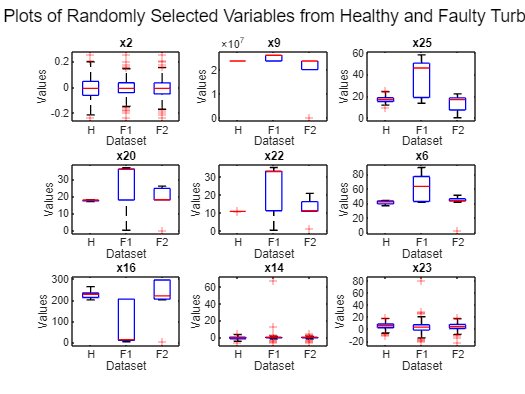

% Choose 9 random variables from the Healthy_turbine dataset
numVars = width(Healthy_turbine);
randomIndices = randperm(numVars, 9); % Randomly select 9 indices

% Select the random variables from each dataset
selectedVars = Healthy_turbine.Properties.VariableNames(randomIndices);

% Combine the selected data for visualization
combinedData = [table2array(Healthy_turbine(:, selectedVars)); 
                table2array(Faulty_turbine1(:, selectedVars)); 
                table2array(Faulty_turbine2(:, selectedVars))];

% Create a categorical variable for the dataset labels
labels = [repmat({'H'}, size(Healthy_turbine, 1), 1); 
          repmat({'F1'}, size(Faulty_turbine1, 1), 1); 
          repmat({'F2'}, size(Faulty_turbine2, 1), 1)];

% Convert to a table for easier manipulation
combinedTable = array2table(combinedData, 'VariableNames', selectedVars);
combinedTable.Labels = labels;

% Create box plots for each selected variable using subplots
figure;
for i = 1:length(selectedVars)
    subplot(3, 3, i); 
    boxplot(combinedTable{:, i}, combinedTable.Labels);
    title(selectedVars{i});
    xlabel('Dataset');
    ylabel('Values');
end

sgtitle('Box Plots of Randomly Selected Variables from Healthy and Faulty Turbines'); 

## Visualization after standadization

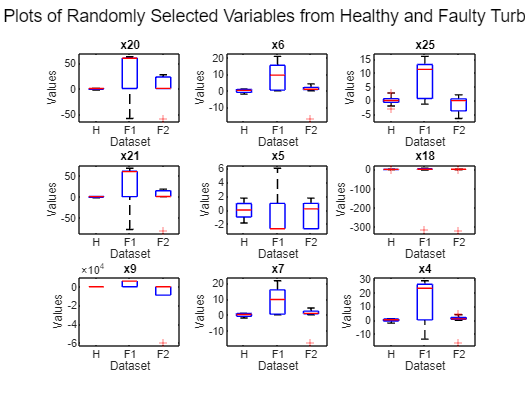

% Choose 9 random variables from the Healthy_turbine dataset
numVars = width(Healthy_turbine_standardized);
randomIndices = randperm(numVars, 9); % Randomly select 9 indices

% Select the random variables from each dataset
selectedVars = Healthy_turbine_standardized.Properties.VariableNames(randomIndices);

% Combine the selected data for visualization
combinedData = [table2array(Healthy_turbine_standardized(:, selectedVars)); 
                table2array(Faulty_turbine1_standardization(:, selectedVars)); 
                table2array(Faulty_turbine2_standardization(:, selectedVars))];

% Create a categorical variable for the dataset labels
labels = [repmat({'H'}, size(Healthy_turbine_standardized, 1), 1); 
          repmat({'F1'}, size(Faulty_turbine1_standardization, 1), 1); 
          repmat({'F2'}, size(Faulty_turbine2_standardization, 1), 1)];

% Convert to a table for easier manipulation
combinedTable = array2table(combinedData, 'VariableNames', selectedVars);
combinedTable.Labels = labels;

% Create box plots for each selected variable using subplots
figure;
for i = 1:length(selectedVars)
    subplot(3, 3, i); 
    boxplot(combinedTable{:, i}, combinedTable.Labels);
    title(selectedVars{i});
    xlabel('Dataset');
    ylabel('Values');
end

sgtitle('Box Plots of Randomly Selected Variables from Healthy and Faulty Turbines'); 

## Principal Component Analysis.

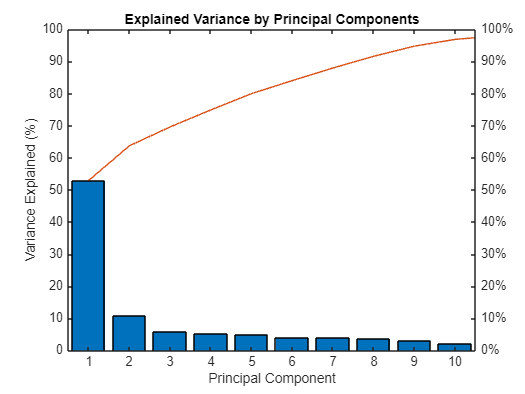

% Assuming Healthy_turbine_standardized is the standardized dataset
X = table2array(Healthy_turbine_standardized);
% Perform PCA on the standardized data
[coeff, score, latent, ~, explained] = pca(X);

% Plot explained variance for each component
figure;
pareto(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Explained Variance by Principal Components');

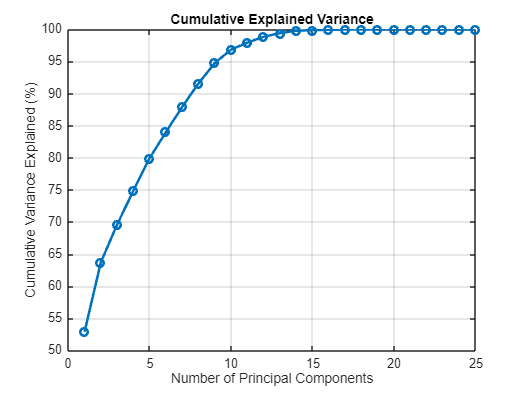


% Cumulative explained variance
cumExplained = cumsum(explained);

% Plot cumulative explained variance
figure;
plot(cumExplained, '-o', 'LineWidth', 2);
xlabel('Number of Principal Components');
ylabel('Cumulative Variance Explained (%)');
title('Cumulative Explained Variance');
grid on;

noPCs = 9; % Number of principal components to use
% Compute the T² statistic using standardized scores
T2 = sum((score(:, 1:noPCs) ./ std(score(:, 1:noPCs))).^2, 2);

% Compute the Squared Prediction Error (SPE)
reconstructed = score(:, 1:noPCs) * coeff(:, 1:noPCs)'; 
SPE = sqrt(sum((X - reconstructed).^2, 2));

% Compute control limits for T²
T2_mean = mean(T2);
T2_std = std(T2);
T2_limit_2sd = T2_mean + 2 * T2_std 

T2_limit_2sd = 66.7814

T2_limit_3sd = T2_mean + 3 * T2_std 

T2_limit_3sd = 95.6749

% Compute control limits for SPE
SPE_mean = mean(SPE);
SPE_std = std(SPE);
SPE_limit_2sd = SPE_mean + 2 * SPE_std 

SPE_limit_2sd = 1.9365

SPE_limit_3sd = SPE_mean + 3 * SPE_std 

SPE_limit_3sd = 2.3764

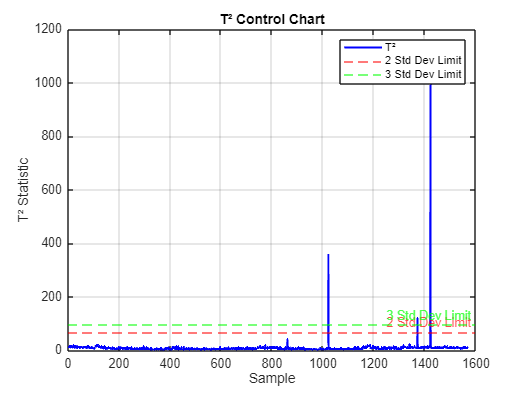

% Plot T² control chart
figure;
plot(T2, 'b-', 'LineWidth', 1.5); % Plot T² statistic
hold on;
yline(T2_limit_2sd, 'r--', '2 Std Dev Limit'); % 2 std dev limit
yline(T2_limit_3sd, 'g--', '3 Std Dev Limit'); % 3 std dev limit
title('T² Control Chart');
xlabel('Sample');
ylabel('T² Statistic');
legend('T²', '2 Std Dev Limit', '3 Std Dev Limit');
grid on;
hold off;

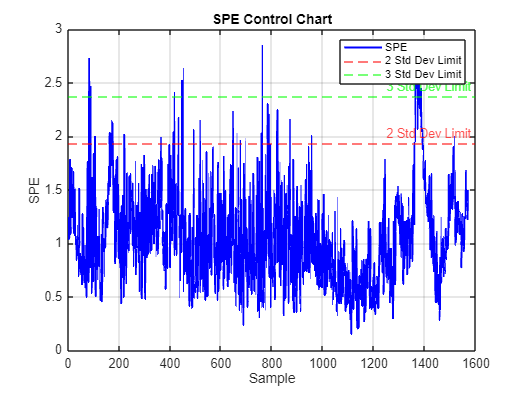


% Plot SPE control chart
figure;
plot(SPE, 'b-', 'LineWidth', 1.5); % Plot SPE
hold on;
yline(SPE_limit_2sd, 'r--', '2 Std Dev Limit'); % 2 std dev limit
yline(SPE_limit_3sd, 'g--', '3 Std Dev Limit'); % 3 std dev limit
title('SPE Control Chart');
xlabel('Sample');
ylabel('SPE');
legend('SPE', '2 Std Dev Limit', '3 Std Dev Limit');
grid on;
hold off;

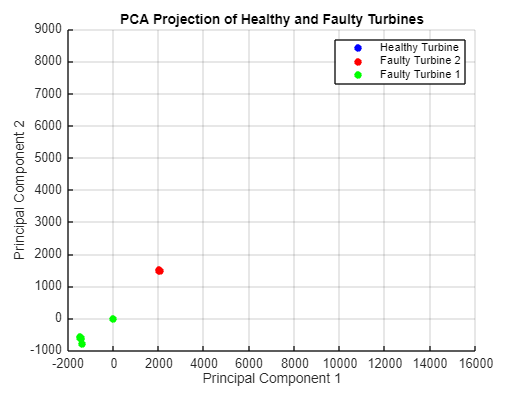

% Now project Faulty_turbine2 and Faulty_turbine1 onto the PCA model

% Standardize the faulty turbines using the same mean and standard deviation of the healthy data
Faulty_turbine2_projected = table2array(Faulty_turbine2_standardization) * coeff;
Faulty_turbine1_projected = table2array(Faulty_turbine1_standardization) * coeff;

% Create a new figure for the plot
figure;

% Plot the healthy turbine data projections (score) in blue
scatter(score(:,1), score(:,2), 'b', 'filled'); hold on; 

% Plot the projections of Faulty Turbine 2 in red
scatter(Faulty_turbine2_projected(:,1), Faulty_turbine2_projected(:,2), 'r', 'filled');

% Plot the projections of Faulty Turbine 1 in green
scatter(Faulty_turbine1_projected(:,1), Faulty_turbine1_projected(:,2), 'g', 'filled');

% Add a legend to identify the data points
legend('Healthy Turbine', 'Faulty Turbine 2', 'Faulty Turbine 1');

% Label the x-axis and y-axis
xlabel('Principal Component 1');
ylabel('Principal Component 2');

% Set the title of the plot
title('PCA Projection of Healthy and Faulty Turbines');

% Turn on the grid for better visibility
grid on;

% Release the hold on the current figure so further plotting does not affect this plot
hold off;

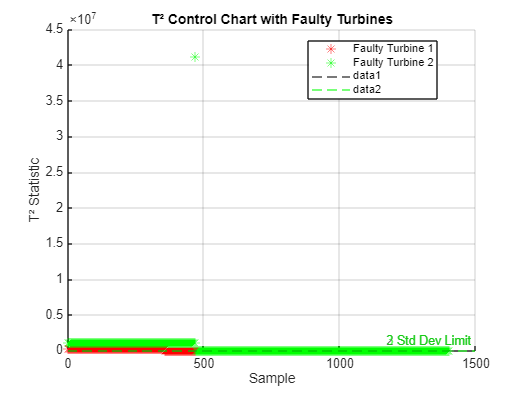

% Project the faulty turbines using the PCA model from healthy turbines
Faulty_turbine1_score = table2array(Faulty_turbine1_standardization) * coeff; 
Faulty_turbine2_score = table2array(Faulty_turbine2_standardization) * coeff; 
% Calculate T² for the projected faulty turbines
Faulty_turbine1_T2 = sum((Faulty_turbine1_score(:, 1:noPCs) ./ std(score(:, 1:noPCs))).^2, 2);
Faulty_turbine2_T2 = sum((Faulty_turbine2_score(:, 1:noPCs) ./ std(score(:, 1:noPCs))).^2, 2);

% Calculate SPE for the projected faulty turbines
Faulty_turbine1_reconstructed = Faulty_turbine1_score(:, 1:noPCs) * coeff(:, 1:noPCs)'; 
Faulty_turbine1_SPE = sqrt(sum((Faulty_turbine1 - Faulty_turbine1_reconstructed).^2, 2));

Faulty_turbine2_reconstructed = Faulty_turbine2_score(:, 1:noPCs) * coeff(:, 1:noPCs)'; 
Faulty_turbine2_SPE = sqrt(sum((Faulty_turbine2 - Faulty_turbine2_reconstructed).^2, 2));

% Plot T² values for faulty turbines
figure;
hold on;
plot(Faulty_turbine1_T2, 'r*', 'MarkerSize', 8, 'DisplayName', 'Faulty Turbine 1'); % Faulty turbine 1
plot(Faulty_turbine2_T2, 'g*', 'MarkerSize', 8, 'DisplayName', 'Faulty Turbine 2'); % Faulty turbine 2
yline(T2_limit_2sd, 'k--', '2 Std Dev Limit'); % 2 std dev limit
yline(T2_limit_3sd, 'g--', '3 Std Dev Limit'); % 3 std dev limit
title('T² Control Chart with Faulty Turbines');
xlabel('Sample');
ylabel('T² Statistic');
legend('Location', 'best');
grid on;
hold off;

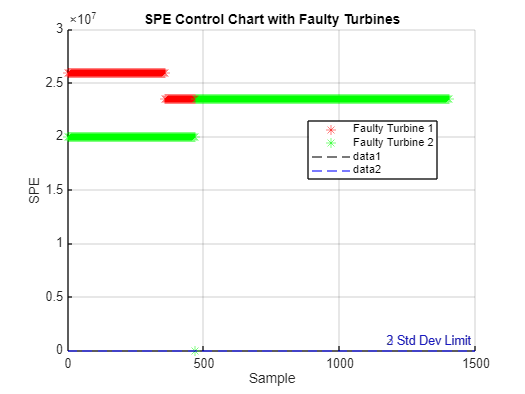


% Plot SPE values for faulty turbines
figure;
hold on;
plot(table2array(Faulty_turbine1_SPE), 'r*', 'MarkerSize', 8, 'DisplayName', 'Faulty Turbine 1');
plot(table2array(Faulty_turbine2_SPE), 'g*', 'MarkerSize', 8, 'DisplayName', 'Faulty Turbine 2'); 
yline(SPE_limit_2sd, 'k--', '2 Std Dev Limit'); 
yline(SPE_limit_3sd, 'b--', '3 Std Dev Limit'); 
title('SPE Control Chart with Faulty Turbines');
xlabel('Sample');
ylabel('SPE');
legend('Location', 'best');
grid on;
hold off;